# CMC Instantaneous Axis of Rotation Calculator

Excel File Name:

fileName = "test.xlsx";

Plot the path of the CMC tracker:

inlcude start and ending frame (pose)

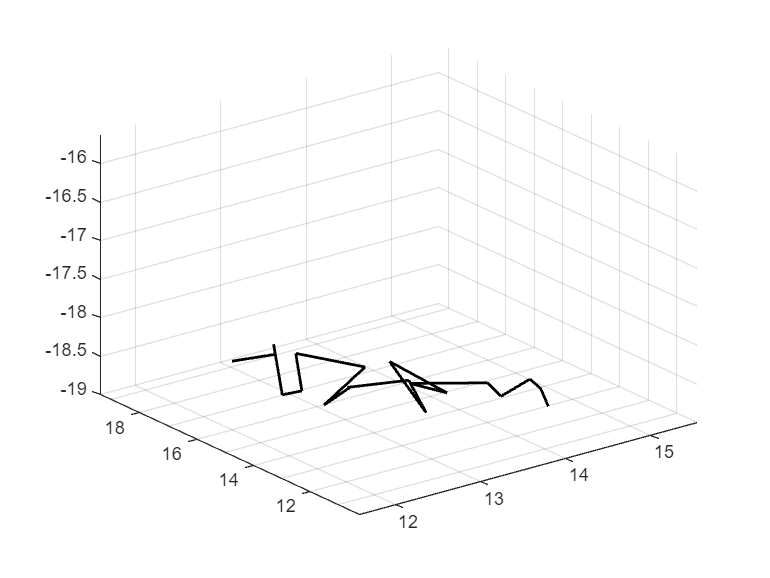

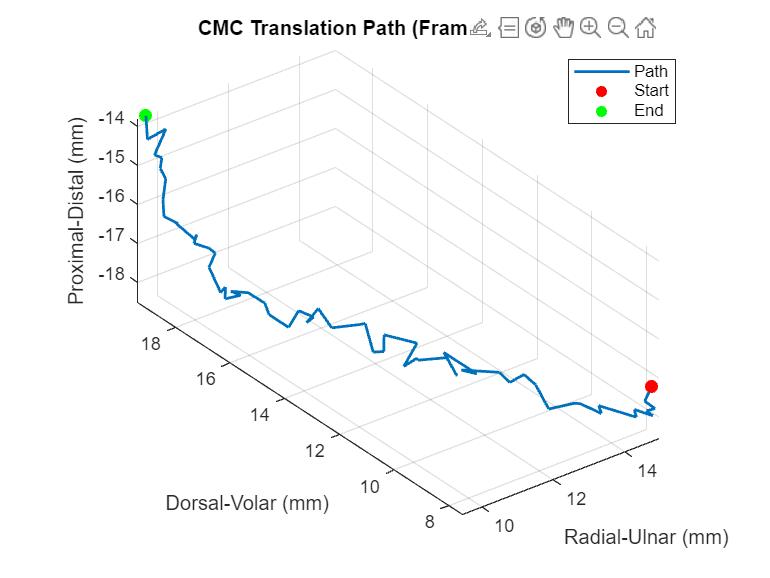

startFrame = 200;
endFrame = 600;
animationSpeed = 0.0001; %from 0 to 0.001
plotCMCTranslationPath(fileName, startFrame, endFrame, animationSpeed);

--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

Calculate Transformation Matrix

buildCMCTransformMatrix(fileName);

First rotation matrix:
    0.7910   -0.4695   -0.3924
    0.5630    0.8096    0.1662
    0.2396   -0.3523    0.9047

Orthogonality check:
    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000

Determinant of first rotation matrix:
    1.0000

First translation vector:
   14.8767
    7.3753
  -15.2181

First homogeneous transform T_all(:,:,1):
    0.7910   -0.4695   -0.3924   14.8767
    0.5630    0.8096    0.1662    7.3753
    0.2396   -0.3523    0.9047  -15.2181
         0         0         0    1.0000

Finished building transformation matrices and saved to CMC_T_matrices.mat


%plotInstantaneousAxisCMC("CMC_T_matrices.mat", 10, 50, 1, 15, startFrame, endFrame, 19);

--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

Overlap: 0% 50% and 95%

overlap_1 = 0;
overlap_2 = 50;
overlap_3 = 80;

Window: 5, 15, and 30

dt_1 = 4;
dt_2 = 19;
dt_3 = 49;

--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

**Overlap 1**

Window 1 = 5

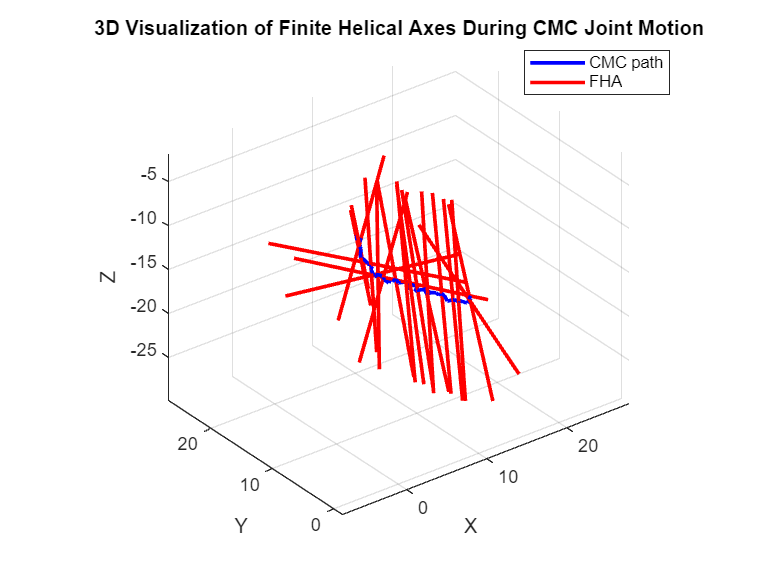

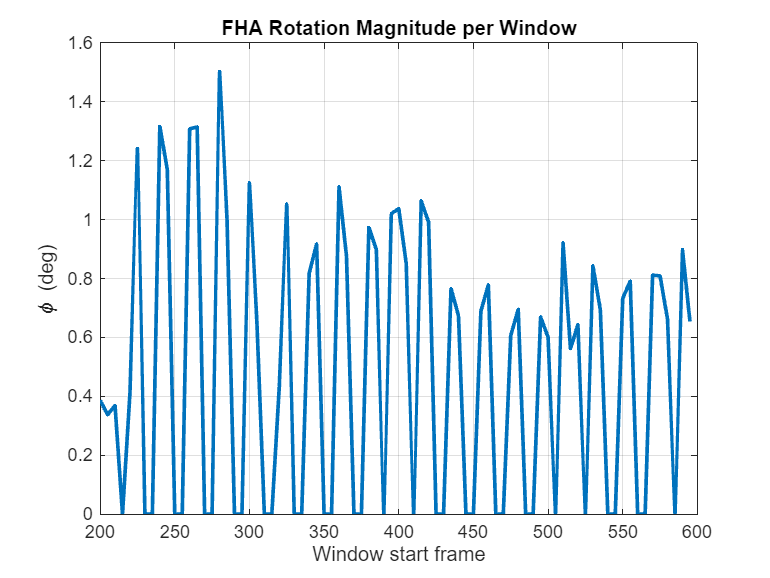

Selected frame range: 200 to 600
dt: 4
Window length: 5 frames
Overlap: 0.0%
Window step: 5 frames
Total FHA windows attempted: 80
Valid FHA windows: 80
Ignoring first 1 FHA windows
Valid FHA windows used in average: 79
Mean global FHA direction = [0.0066 0.6645 0.7472]


plotOverlappedFHA_CMC("CMC_T_matrices.mat", 10, 4, 3, startFrame, endFrame, dt_1, overlap_1, 1);

Window 2

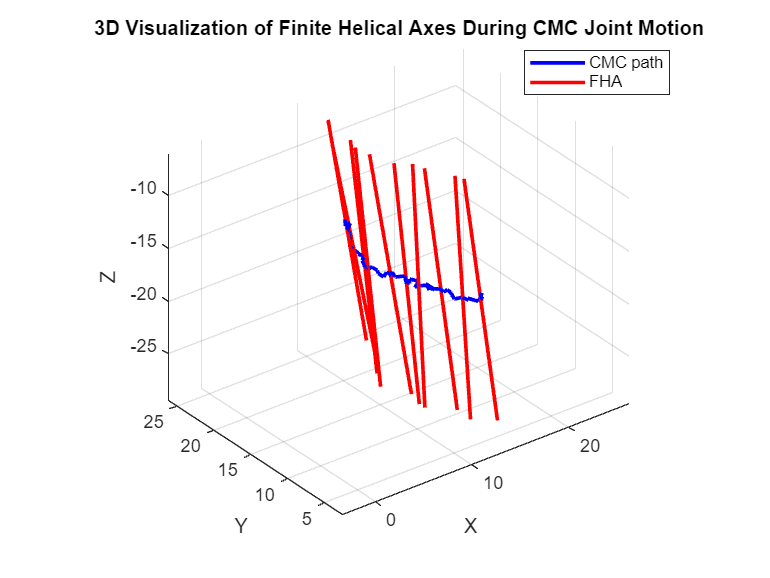

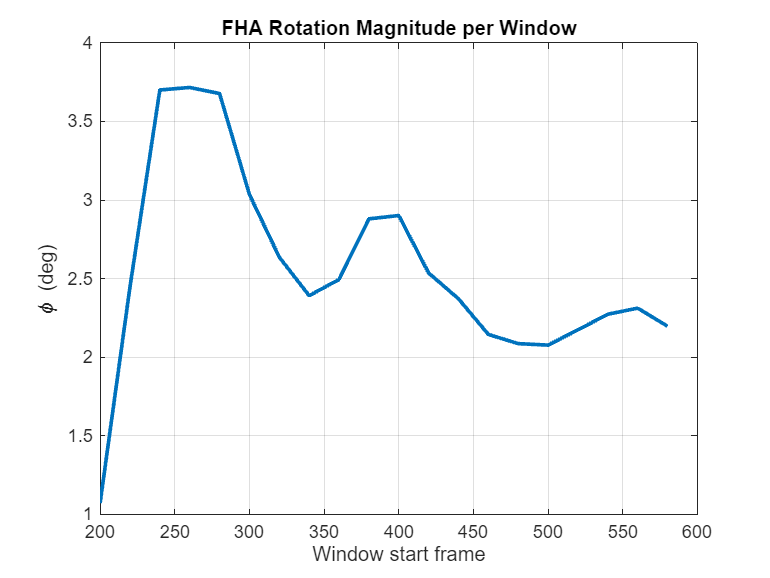

Selected frame range: 200 to 600
dt: 19
Window length: 20 frames
Overlap: 0.0%
Window step: 20 frames
Total FHA windows attempted: 20
Valid FHA windows: 20
Ignoring first 1 FHA windows
Valid FHA windows used in average: 19
Mean global FHA direction = [0.2874 0.5733 0.7673]


plotOverlappedFHA_CMC("CMC_T_matrices.mat", 10, 2, 3, startFrame, endFrame, dt_2, overlap_1, 1);

Window 3

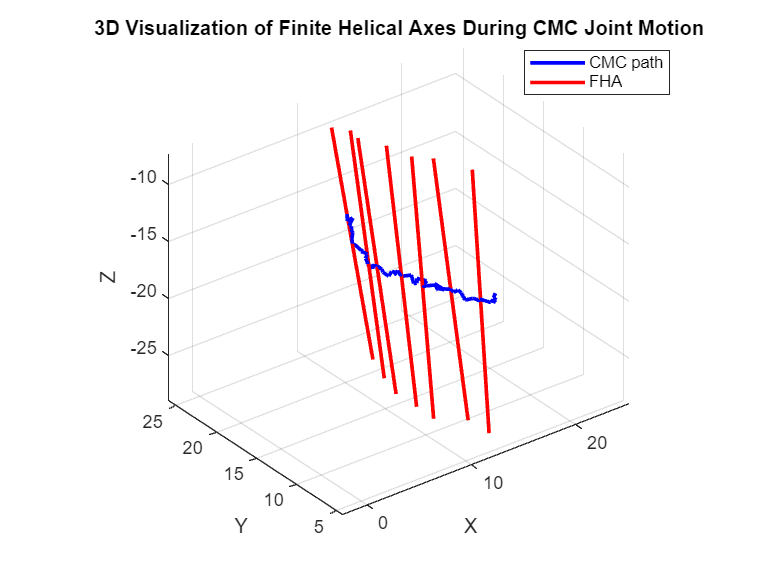

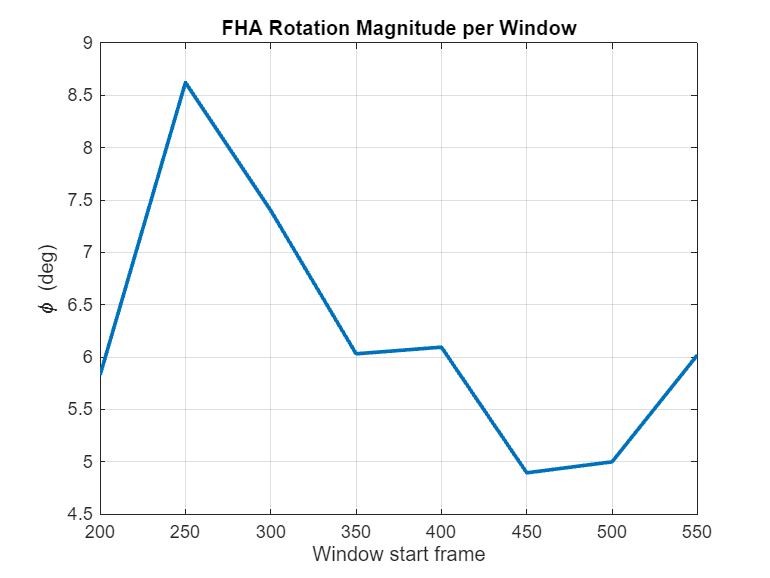

Selected frame range: 200 to 600
dt: 49
Window length: 50 frames
Overlap: 0.0%
Window step: 50 frames
Total FHA windows attempted: 8
Valid FHA windows: 8
Ignoring first 1 FHA windows
Valid FHA windows used in average: 7
Mean global FHA direction = [0.2943 0.5793 0.7602]


plotOverlappedFHA_CMC("CMC_T_matrices.mat", 10, 1, 3, startFrame, endFrame, dt_3, overlap_1, 1);

--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

**Overlap 2**

Window 1

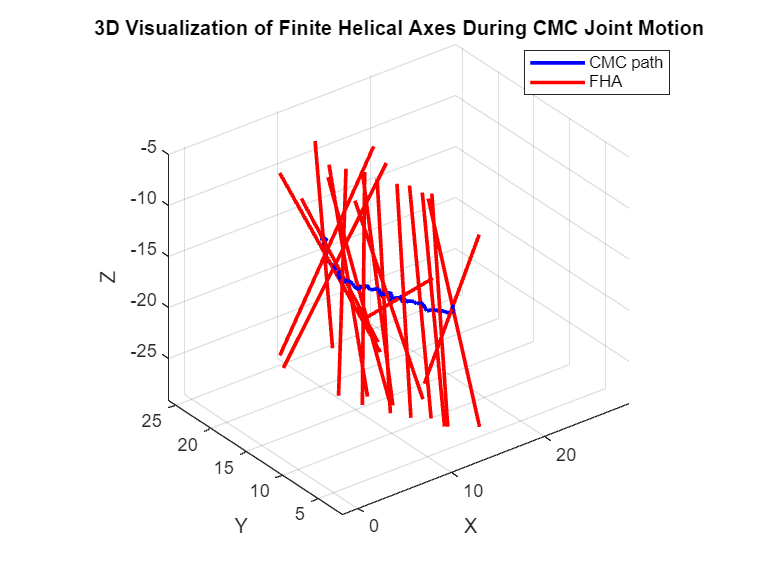

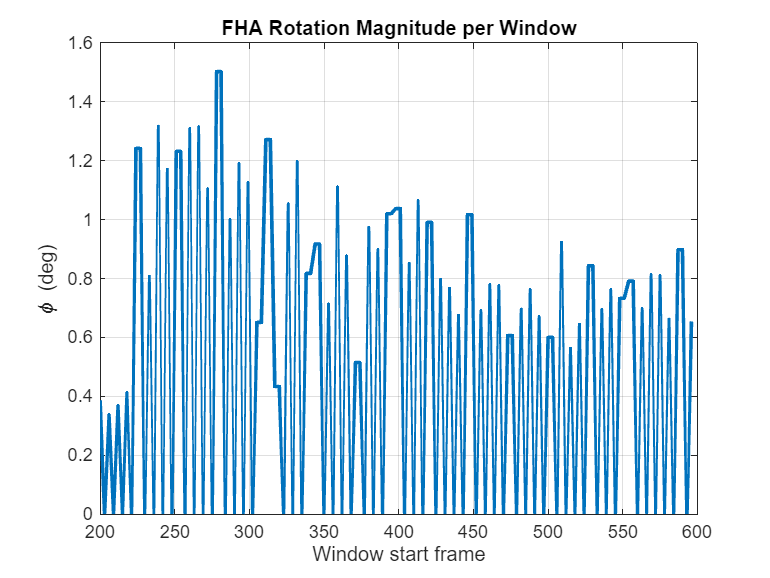

Selected frame range: 200 to 600
dt: 4
Window length: 5 frames
Overlap: 50.0%
Window step: 3 frames
Total FHA windows attempted: 133
Valid FHA windows: 133
Ignoring first 1 FHA windows
Valid FHA windows used in average: 132
Mean global FHA direction = [0.2041 0.5397 0.8168]


plotOverlappedFHA_CMC("CMC_T_matrices.mat", 10, 7, 3, startFrame, endFrame, dt_1, overlap_2, 1);

Window 2

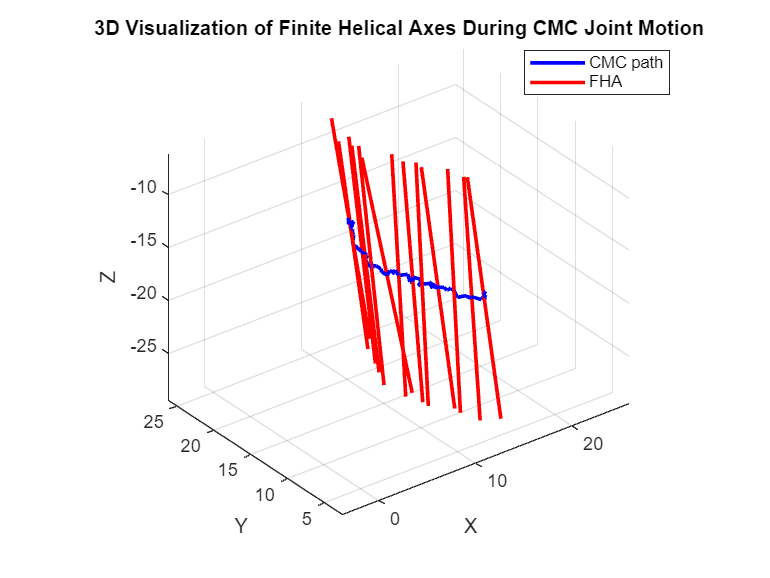

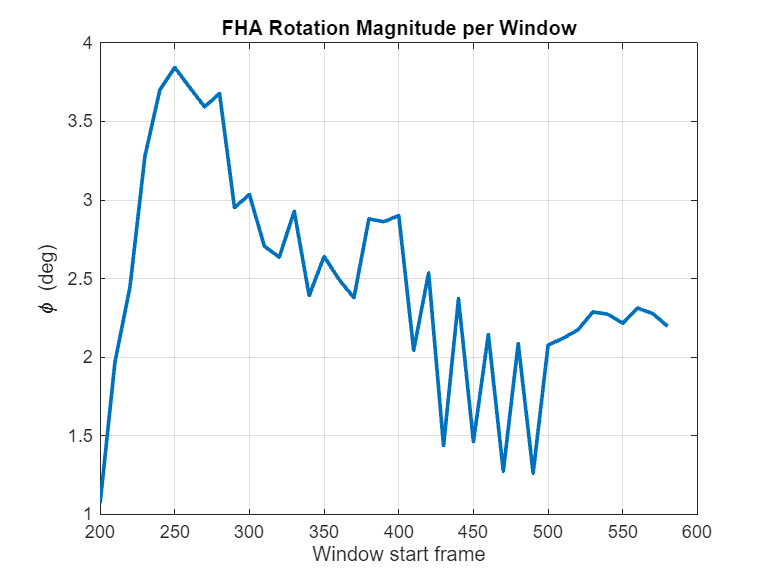

Selected frame range: 200 to 600
dt: 19
Window length: 20 frames
Overlap: 50.0%
Window step: 10 frames
Total FHA windows attempted: 39
Valid FHA windows: 39
Ignoring first 2 FHA windows
Valid FHA windows used in average: 37
Mean global FHA direction = [0.2883 0.5734 0.7669]


plotOverlappedFHA_CMC("CMC_T_matrices.mat", 10, 3, 3, startFrame, endFrame, dt_2, overlap_2, 2);

Window 3

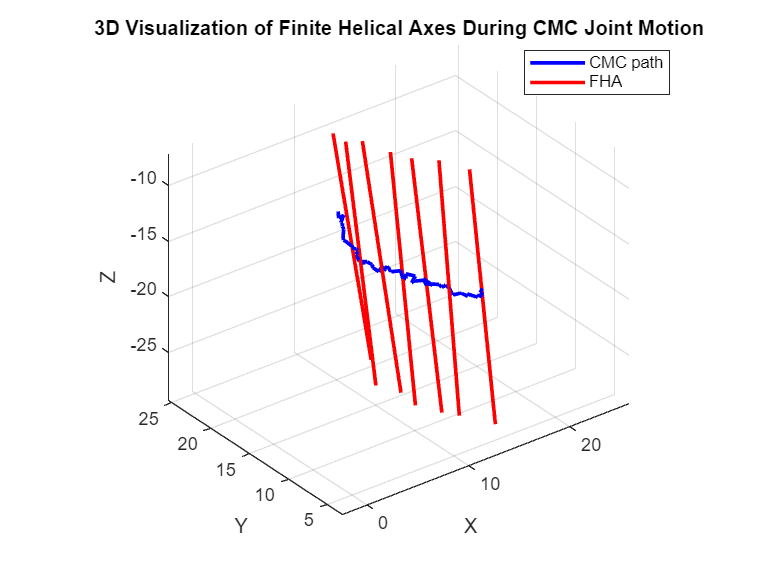

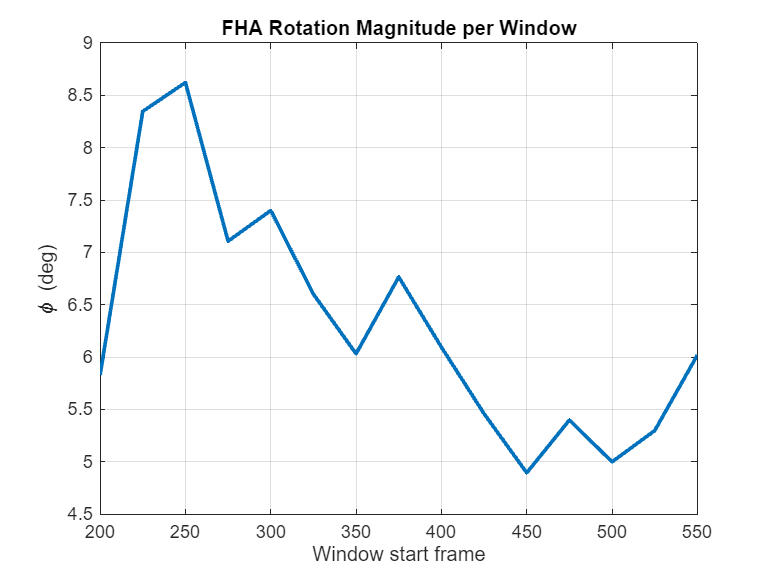

Selected frame range: 200 to 600
dt: 49
Window length: 50 frames
Overlap: 50.0%
Window step: 25 frames
Total FHA windows attempted: 15
Valid FHA windows: 15
Ignoring first 1 FHA windows
Valid FHA windows used in average: 14
Mean global FHA direction = [0.2883 0.5704 0.7691]


plotOverlappedFHA_CMC("CMC_T_matrices.mat", 10, 2, 3, startFrame, endFrame, dt_3, overlap_2, 1);

--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

**Overlap 3**

Window 1

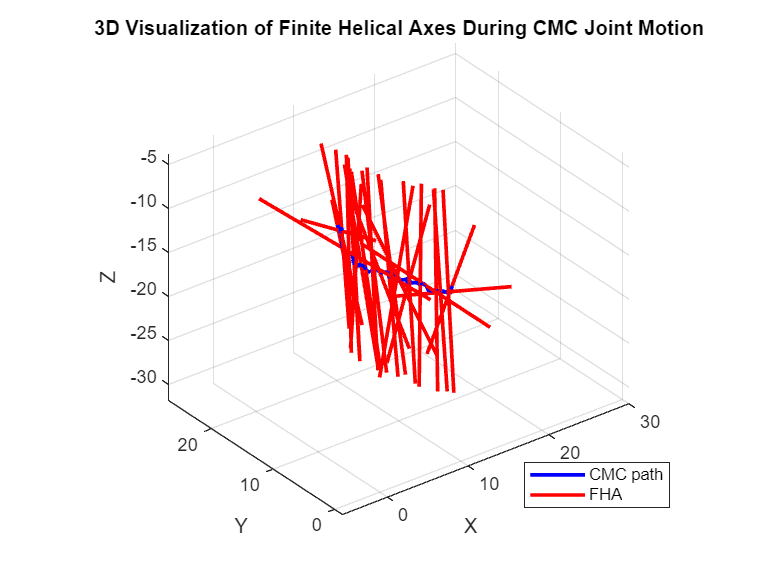

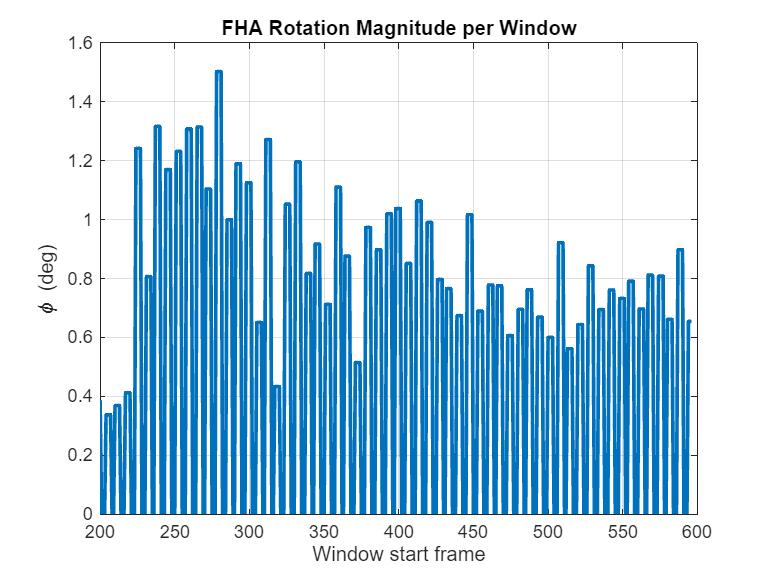

Selected frame range: 200 to 600
dt: 4
Window length: 5 frames
Overlap: 80.0%
Window step: 1 frames
Total FHA windows attempted: 397
Valid FHA windows: 397
Ignoring first 1 FHA windows
Valid FHA windows used in average: 396
Mean global FHA direction = [-0.3540 -0.3712 -0.8584]


plotOverlappedFHA_CMC("CMC_T_matrices.mat", 10, 15, 3, startFrame, endFrame, dt_1, overlap_3, 1);

Window 2

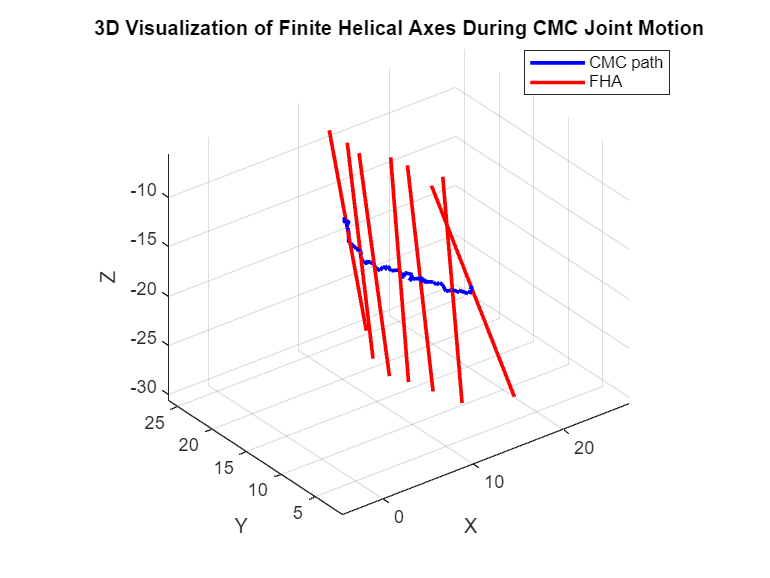

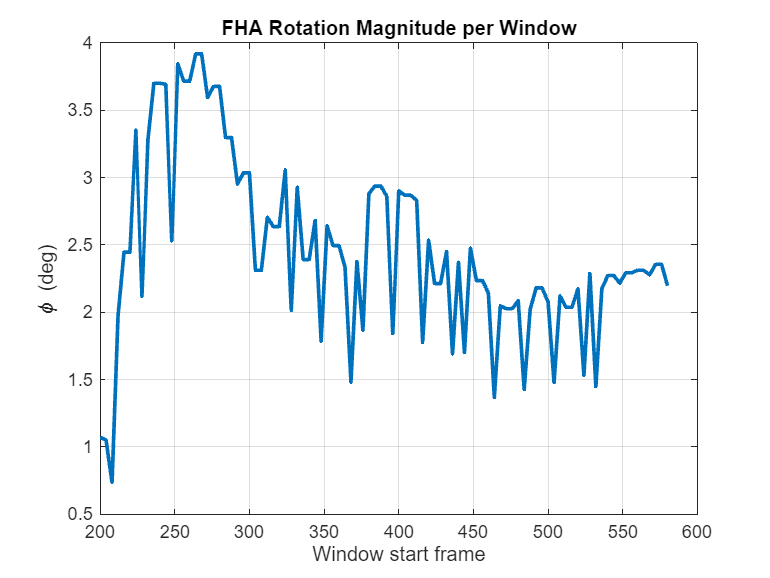

Selected frame range: 200 to 600
dt: 19
Window length: 20 frames
Overlap: 80.0%
Window step: 4 frames
Total FHA windows attempted: 96
Valid FHA windows: 96
Ignoring first 2 FHA windows
Valid FHA windows used in average: 94
Mean global FHA direction = [0.2855 0.5709 0.7698]


plotOverlappedFHA_CMC("CMC_T_matrices.mat", 10, 15, 3, startFrame, endFrame, dt_2, overlap_3, 2);

Window 3

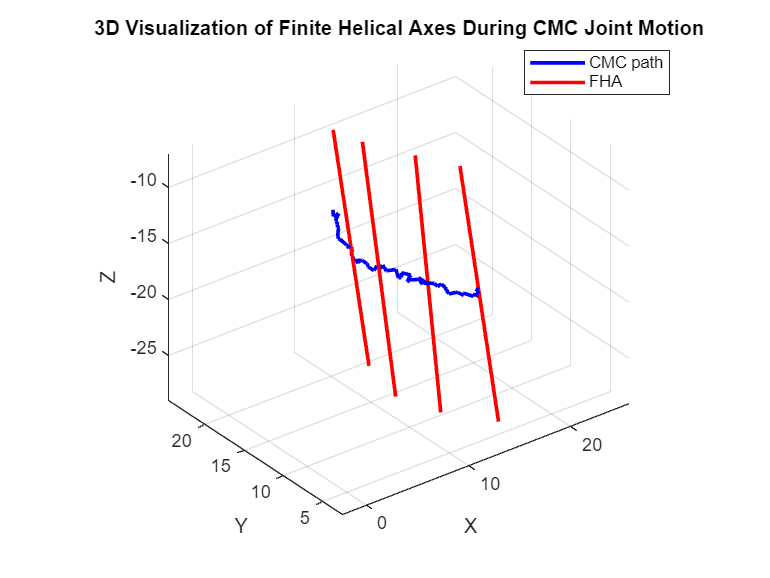

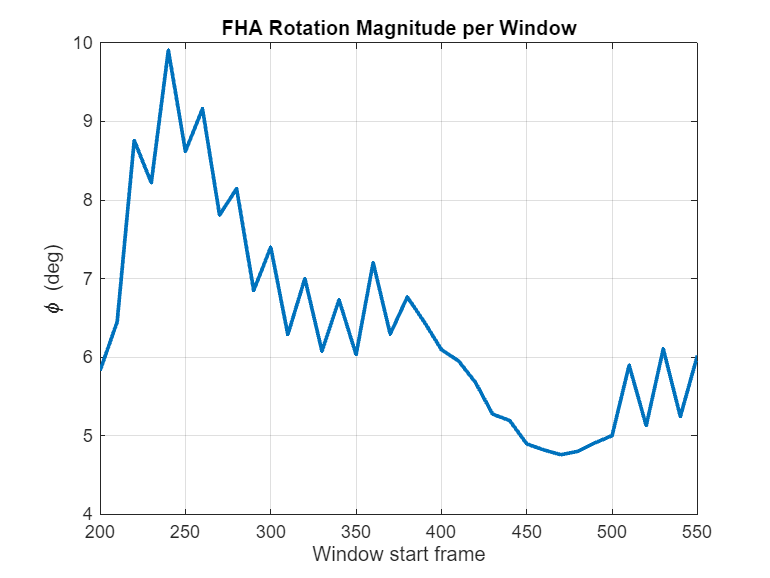

Selected frame range: 200 to 600
dt: 49
Window length: 50 frames
Overlap: 80.0%
Window step: 10 frames
Total FHA windows attempted: 36
Valid FHA windows: 36
Ignoring first 1 FHA windows
Valid FHA windows used in average: 35
Mean global FHA direction = [0.2857 0.5651 0.7740]


plotOverlappedFHA_CMC("CMC_T_matrices.mat", 10, 10, 3, startFrame, endFrame, dt_3, overlap_3, 1);